[numer_indeksu, Edges, I, B, A, b, r] = page_rank()

numer_indeksu = 193577

Edges =      1     1     2     2     2     3     3     3     4     4     5     5     6     6     7     7     8
     4     6     3     4     5     5     6     7     5     6     4     6     4     7     6     8     1


I =    (1,1)        1
   (2,2)        1
   (3,3)        1
   (4,4)        1
   (5,5)        1
   (6,6)        1
   (7,7)        1
   (8,8)        1

B =    (4,1)        1
   (6,1)        1
   (3,2)        1
   (4,2)        1
   (5,2)        1
   (5,3)        1
   (6,3)        1
   (7,3)        1
   (5,4)        1
   (6,4)        1
   (4,5)        1
   (6,5)        1
   (4,6)        1
   (7,6)        1
   (6,7)        1
   (8,7)        1
   (1,8)        1

A =    (1,1)       0.5000
   (2,2)       0.3333
   (3,3)       0.3333
   (4,4)       0.5000
   (5,5)       0.5000
   (6,6)       0.5000
   (7,7)       0.5000
   (8,8)       1.0000

b =     0.0188
    0.0188
    0.0188
    0.0188
    0.0188
    0.0188
    0.0188
    0.0188


r =     0.0868
    0.0188
    0.0241
    0.2354
    0.1309
    0.2795
    0.1444
    0.0801


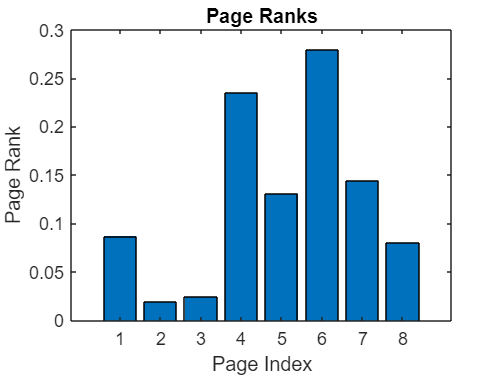

plot_PageRank(r)

function [numer_indeksu, Edges, I, B, A, b, r] = page_rank()
numer_indeksu = 193577;
N = 8;
d = 0.85;
Edges = [1, 1, 2, 2, 2, 3, 3, 3, 4, 4, 5, 5, 6, 6, 7, 7, 8;
         4, 6, 3, 4, 5, 5, 6, 7, 5, 6, 4, 6, 4, 7, 6, 8, 1];

%Edges = [1, 1, 2, 2, 2, 3, 3, 3, 4, 4, 5, 5, 6, 6, 6, 7, 8;
%         4, 6, 3, 4, 5, 5, 6, 7, 5, 6, 4, 6, 4, 7, 8, 6, 1];

I = speye(N);
B = sparse( Edges(2,:),Edges(1,:),1,N,N);
L = sum(B);
A = spdiags(1./L(:),0,N,N);
b = (1-d)/N * ones(N, 1);
M = I - d * B * A;
r = M \ b;

end

function plot_PageRank(r)
    bar(r);
    xlabel('Page Index');
    ylabel('Page Rank');
    title('Page Ranks');
end
